## Detección Digital en Banda Base 

## justificar por qué baja error según aumenta N

### Introducción

En esta sesión ampliaremos el trabajo realizado anteriormente mediante la implementación del  detector digital que trabaja con el demodulador para decidir qué símbolo ha sido transmitido  con mayor probabilidad. 

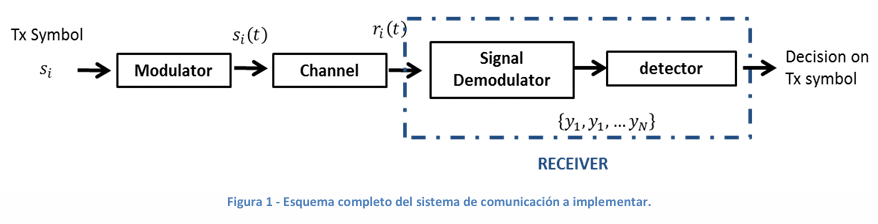

### Modulador

Usando las bases de la P1 vamos a generar los siguientes símbolos

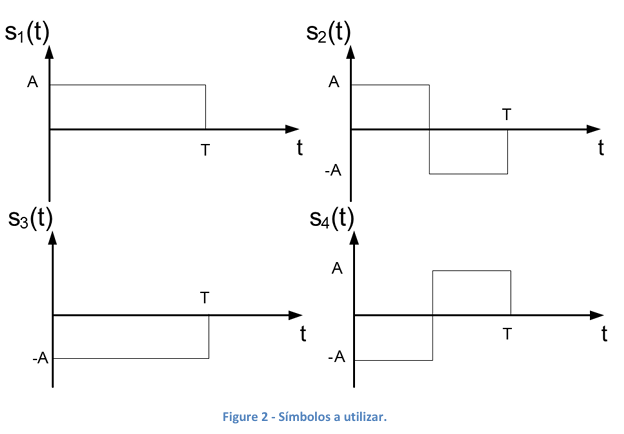

### Ejercicio 2.1

Implemente el bloque modulador.  Como puede ver en la Figura 1, el bloque del modulador es  un bloque que tiene como entrada la sucesión de bits a transmitir1 y, como salida las  correspondientes señales moduladas.   

Desarrolle un código que implemente el comportamiento deseado, apoyándose si así lo cree  conveniente en el código desarrollado en la práctica anterior. La función debe generar el vector  de muestras que define la concatenación de varios símbolos, e incluir como parámetros de  entrada al menos el número total de símbolos de salida, N, y los vectores de las funciones base  φ1, φ2. Por ejemplo, si N = 10, el vector de salida del modulador ha de contener la  correspondiente señal modulada para estos 10 símbolos.   

Para la generación del modulador asuma que T = 10 ms y utilice un periodo de muestreo de Ts  = T/20, tal y como hizo en la sesión anterior.  

%% LAB 1 - PARTE 2: DETECCIÓN DIGITAL EN BANDA BASE
% 2. MODULADOR DIGITAL (M = 4 SÍMBOLOS)

clear; close all; clc;

% --- Parámetros base heredados de P0 y P1 ---
T  = 10e-3;      % 10 ms = 0.01 s
Ts = T / 20;     % 0.5 ms
L  = T / Ts;     % 20 muestras por símbolo

% 1. Reutilizamos la función de la P0/P1 para obtener s1, s2 y las bases phi
[s1, s2, ~] = generar_senales_fig1(T, Ts);
phi1 = s1 / sqrt(T);
phi2 = s2 / sqrt(T);

% 2. Definimos una secuencia de prueba de N = 10 símbolos
rng(42); % Semilla fija para reproducibilidad
N = 10;
s_test = randi([1, 4], 1, N);
fprintf('Vector de entrada s (%d símbolos):\n', N);

Vector de entrada s (10 símbolos):


disp(s_test);

     2     4     3     3     1     1     1     4     3     3



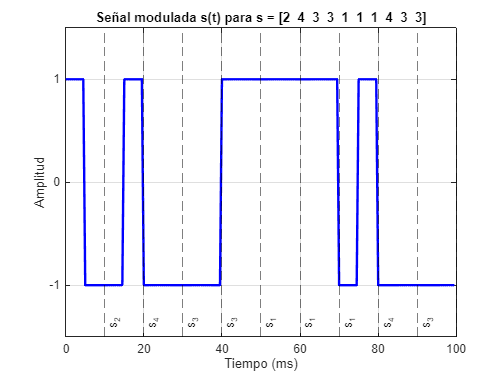


% 3. Llamada al Modulador
[s_t, ~] = modulador(s_test, phi1, phi2);

% Vector de tiempos total en milisegundos
t_total_ms = (0:length(s_t)-1) * Ts * 1e3;

% 4. Representación gráfica del resultado de la prueba
figure('Name', 'Ejercicio 2.1 - Salida del Modulador (N=10)', 'Color', 'w');
plot(t_total_ms, s_t, 'b-', 'LineWidth', 2); grid on;
title(['Señal modulada s(t) para s = [', num2str(s_test), ']']);
xlabel('Tiempo (ms)'); ylabel('Amplitud');
xlim([0, N * T * 1e3]);
ylim([-1.5, 1.5]);
yticks([-1, 0, 1]);
yticklabels({'-1', '0', '1'});

% Marcar las fronteras de cada símbolo para verificar visualmente
hold on;
for k = 1:N
    xline(k * T * 1e3, '--k', sprintf('s_%d', s_test(k)), ...
          'LabelVerticalAlignment', 'bottom', 'Alpha', 0.5);
end
hold off;

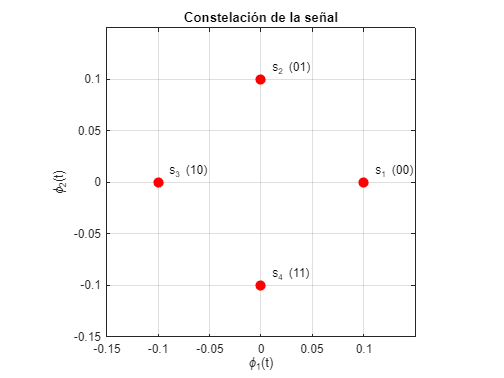

c = [ 0.1,    0;   ... % s1
        0,  0.1;   ... % s2
     -0.1,    0;   ... % s3
        0, -0.1];      % s4
figure('Name', 'Figure 1: Constelación', 'Color', 'w');
plot(c(:,1), c(:,2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
grid on; axis equal;
xlabel('\phi_1(t)'); ylabel('\phi_2(t)');
title('Constelación de la señal');
xlim([-0.15, 0.15]); ylim([-0.15, 0.15]);
text(c(:,1)+0.01, c(:,2)+0.01, {'s_1 (00)', 's_2 (01)', 's_3 (10)', 's_4 (11)'});

### 3. Demodulador

Ejercicio 3.1 (2 puntos)  Implementar el bloque demodulador basándose en el conjunto demodulador-muestreador de  la sesión anterior. La entrada al bloque ha de ser el vector de muestras temporales de N  símbolos, y la salida los vectores de las salidas de las dos ramas del correlador, muestreadas en  los instantes k·T, k=1...N, es decir, cada vector de salida ha de tener una longitud N.  Realice alguna prueba, por ejemplo con N=10, mostrando que las salidas del demodulador se  corresponden con los coeficientes de las funciones base asociados a los símbolos de entrada.  

¿Qué hace este bloque?

- Recibe la señal continua r(t)*r*(*t*) (que dura N×T*N*×*T*).

- Para cada ranura temporal de símbolo k∈[1,N]*k*∈[1,*N*], calcula la integral de correlación con las bases ϕ1*ϕ*1� y ϕ2*ϕ*2�: y1(k)=∫(k−1)TkTr(t)⋅ϕ1(t)dt≈∑n=1Lrk[n]⋅ϕ1[n]⋅Ts*y*1�(*k*)=∫(*k*−1)*T**k**T*�*r*(*t*)⋅*ϕ*1�(*t*)*d**t*≈∑*n*=1*L*�*r**k*�[*n*]⋅*ϕ*1�[*n*]⋅*T**s*� y2(k)=∫(k−1)TkTr(t)⋅ϕ2(t)dt≈∑n=1Lrk[n]⋅ϕ2[n]⋅Ts*y*2�(*k*)=∫(*k*−1)*T**k**T*�*r*(*t*)⋅*ϕ*2�(*t*)*d**t*≈∑*n*=1*L*�*r**k*�[*n*]⋅*ϕ*2�[*n*]⋅*T**s*�

- En un canal sin ruido (r=s*r*=*s*):Las salidas y1(k)*y*1�(*k*) y y2(k)*y*2�(*k*) deben ser exactamente los coeficientes cij*c**ij*� de la tabla:

- Si se envió s1→[y1,y2]=[+0.1,0]*s*1�→[*y*1�,*y*2�]=[+**0.1**,**0**]

- Si se envió s2→[y1,y2]=[0,+0.1]*s*2�→[*y*1�,*y*2�]=[**0**,+**0.1**]

- Si se envió s3→[y1,y2]=[−0.1,0]*s*3�→[*y*1�,*y*2�]=[−**0.1**,**0**]

- Si se envió s4→[y1,y2]=[0,−0.1]*s*4�→[*y*1�,*y*2�]=[**0**,−**0.1**]

%% EJERCICIO 3.1: DEMODULADOR (PRUEBA CON N = 10 SÍMBOLOS)

% 1. En este apartado no hay ruido: r_t = s_t
r_t = s_t;

% 2. Llamada al Demodulador
[y1, y2] = demoduladorp12(r_t, phi1, phi2, Ts);

% 3. Matriz de coeficientes teóricos de la constelación
% Fila 1 = s1, Fila 2 = s2, Fila 3 = s3, Fila 4 = s4
C_teorica = [ 0.1,    0;   ... % s1
                0,  0.1;   ... % s2
             -0.1,    0;   ... % s3
                0, -0.1];      % s4

% Coeficientes teóricos exactos que debían salir para los símbolos transmitidos
c_esperados = C_teorica(s_test, :); % Matriz 10 x 2: [c_esperado_1, c_esperado_2]
c_obtenidos = [y1', y2'];           % Matriz 10 x 2 con las salidas del demodulador

% 4. Cálculo del error máximo absoluto (debe ser 0)
error_maximo = max(abs(c_obtenidos(:) - c_esperados(:)));
fprintf('\n--- Verificación Numérica del Demodulador ---\n');


--- Verificación Numérica del Demodulador ---


fprintf('Error máximo absoluto en los coeficientes: %.2e\n', error_maximo);

Error máximo absoluto en los coeficientes: 0.00e+00


if error_maximo < 1e-12
    disp('-> Confirmado: Las salidas coinciden EXACTAMENTE con los coeficientes teóricos (Error = 0).');
end

-> Confirmado: Las salidas coinciden EXACTAMENTE con los coeficientes teóricos (Error = 0).



% 5. Tabla comparativa detallada
k_vec = 1:N;
tabla_verificacion = table(k_vec', s_test', ...
                           c_esperados(:,1), y1', ...
                           c_esperados(:,2), y2', ...
     'VariableNames', {'Simbolo_k', 'Simbolo_Tx', 'c1_Teorico', 'y1_Obtenido', 'c2_Teorico', 'y2_Obtenido'});
disp(tabla_verificacion);

    Simbolo_k    Simbolo_Tx    c1_Teorico    y1_Obtenido    c2_Teorico    y2_Obtenido
    _________    __________    __________    ___________    __________    ___________

        1            2               0             0            0.1           0.1    
        2            4               0             0           -0.1          -0.1    
        3            3            -0.1          -0.1              0             0    
        4            3            -0.1          -0.1              0             0    
        5            1             0.1           0.1              0             0    
        6            1             0.1           0.1              0             0    
        7            1             0.1           0.1              0             0    
        8            

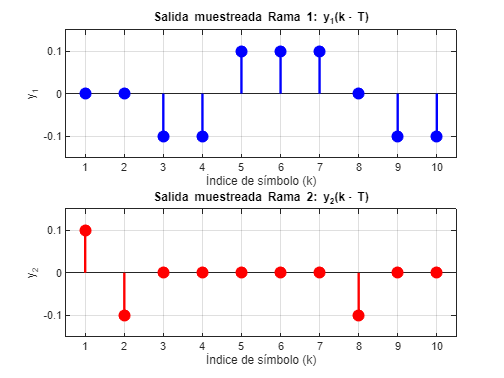


% 6. Representación gráfica (Figure 3: Ejercicio 3.1 - Demodulador)
figure('Name', 'Figure 3: Ejercicio 3.1 - Demodulador', 'Color', 'w');

subplot(2, 1, 1);
stem(k_vec, y1, 'b', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b'); grid on;
title('Salida muestreada Rama 1: y_1(k\cdot T)');
xlabel('Índice de símbolo (k)'); ylabel('y_1');
xlim([0.5, N + 0.5]); ylim([-0.15, 0.15]);
yticks([-0.1, 0, 0.1]); yticklabels({'-0.1', '0', '0.1'});

subplot(2, 1, 2);
stem(k_vec, y2, 'r', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r'); grid on;
title('Salida muestreada Rama 2: y_2(k\cdot T)');
xlabel('Índice de símbolo (k)'); ylabel('y_2');
xlim([0.5, N + 0.5]); ylim([-0.15, 0.15]);
yticks([-0.1, 0, 0.1]); yticklabels({'-0.1', '0', '0.1'});

## 4. Detector

El detector recibe los vectores de salida del demodulador, y basándose en esos valores decide  qué símbolo es más probable que fuera transmitido.   Ejercicio 4.1 (3 puntos)  Construya una función (s_det = Detector (y) ) que reciba tantos parámetros de entrada como  salidas tenga el demodulador implementado anteriormente. La misión de dicha función será  decidir cuál de los símbolos fue transmitido.   Integre la función Detector con el resto de las funciones que ha implementado y haga algunas  pruebas para asegurarse del correcto funcionamiento. Muestre y compare los símbolos  detectados con los generados. 

%% EJERCICIO 4.1: DETECTOR (COMPARATIVA SIN RUIDO VS CON RUIDO)

M = 4;
C = [ 0.1,    0;   ... % s1
        0,  0.1;   ... % s2
     -0.1,    0;   ... % s3
        0, -0.1];      % s4

% --- 1. Prueba SIN RUIDO (N = 10) ---
s_det = detector(y1, y2, C);
fprintf('\n--- Ejercicio 4.1 (Sin Ruido) ---\n');


--- Ejercicio 4.1 (Sin Ruido) ---


fprintf('Símbolos generados:  %s\n', num2str(s_test));

Símbolos generados:  2  4  3  3  1  1  1  4  3  3


fprintf('Símbolos detectados: %s\n', num2str(s_det));

Símbolos detectados: 2  4  3  3  1  1  1  4  3  3


fprintf('Errores: %d\n', sum(s_det ~= s_test));

Errores: 0



% --- 2. Prueba CON RUIDO (N2 = 200, sigma = 1.0) ---
rng(1);
N2 = 200;
s2 = randi(M, 1, N2);
s2_t = modulador(s2, phi1, phi2);
r2_t = s2_t + 1.0 * randn(size(s2_t)); % Ruido gaussiano sigma = 1
[y1n, y2n] = demoduladorp12(r2_t, phi1, phi2, Ts);
s2_det = detector(y1n, y2n, C);

fprintf('\n--- Ejercicio 4.1 (Con Ruido, sigma = 1.0, %d símbolos) ---\n', N2);


--- Ejercicio 4.1 (Con Ruido, sigma = 1.0, 200 símbolos) ---


fprintf('Errores detectados: %d de %d (Tasa: %.2f%%)\n', ...
        sum(s2_det ~= s2), N2, (sum(s2_det ~= s2)/N2)*100);

Errores detectados: 0 de 200 (Tasa: 0.00%)


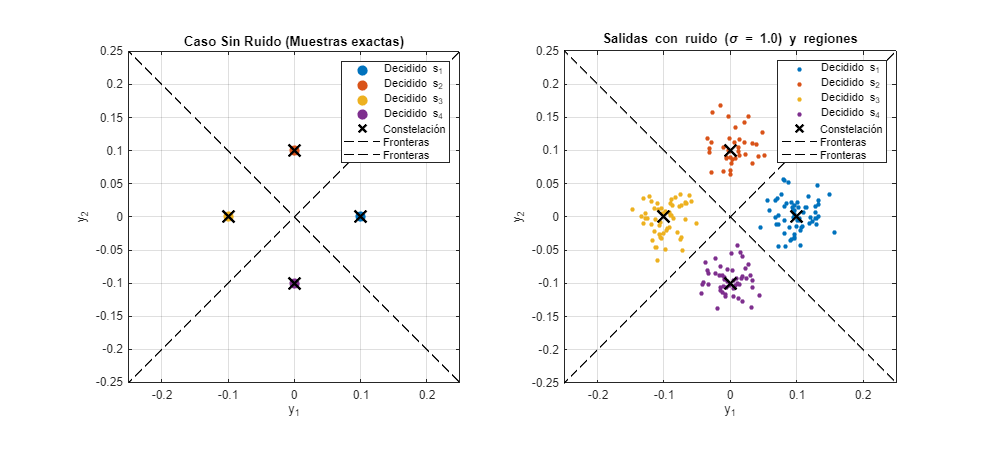


% --- 3. Representación Gráfica: Ambos Casos Lado a Lado ---
figure('Name', 'Ejercicio 4.1 - Detector (Ideal vs Con Ruido)', 'Color', 'w', ...
       'Position', [100, 150, 1100, 500]);

colores = lines(M);

% SUBPLOT 1: Caso Sin Ruido (Ideal)
subplot(1, 2, 1);
for i = 1:M
    idx = (s_det == i);
    plot(y1(idx), y2(idx), 'o', 'Color', colores(i,:), 'MarkerFaceColor', colores(i,:), ...
         'MarkerSize', 8, 'DisplayName', sprintf('Decidido s_%d', i));
    hold on;
end
plot(C(:,1), C(:,2), 'kx', 'MarkerSize', 14, 'LineWidth', 2, 'DisplayName', 'Constelación');
plot([-0.3 0.3], [-0.3 0.3], 'k--', [-0.3 0.3], [0.3 -0.3], 'k--', 'DisplayName', 'Fronteras');
axis equal; axis([-0.25 0.25 -0.25 0.25]); grid on;
xlabel('y_1'); ylabel('y_2');
title('Caso Sin Ruido (Muestras exactas)');
legend('Location', 'northeast');

% SUBPLOT 2: Caso Con Ruido (sigma = 1.0)
subplot(1, 2, 2);
for i = 1:M
    idx = (s2_det == i);
    plot(y1n(idx), y2n(idx), '.', 'Color', colores(i,:), 'MarkerSize', 11, ...
         'DisplayName', sprintf('Decidido s_%d', i));
    hold on;
end
plot(C(:,1), C(:,2), 'kx', 'MarkerSize', 14, 'LineWidth', 2, 'DisplayName', 'Constelación');
plot([-0.3 0.3], [-0.3 0.3], 'k--', [-0.3 0.3], [0.3 -0.3], 'k--', 'DisplayName', 'Fronteras');
axis equal; axis([-0.25 0.25 -0.25 0.25]); grid on;
xlabel('y_1'); ylabel('y_2');
title('Salidas con ruido (\sigma = 1.0) y regiones');
legend('Location', 'northeast');

- Caso sin ruido (Izquierda):En condiciones ideales, las muestras entregadas por el demodulador coinciden de forma exacta con los centroides teóricos de la constelación [ci1,ci2]=(±0.1,0)[*c**i*1�,*c**i*2�]=(±0.1,0) y (0,±0.1)(0,±0.1). Al no existir dispersión alguna, el detector de mínima distancia euclídea clasifica todos los símbolos con una tasa de error del 0%0%.

- Caso con ruido σ=1.0*σ*=1.0 (Derecha):La adición de ruido blanco gaussiano (AWGN) en el canal genera nubes de dispersión circular en torno a cada símbolo transmitido. Las fronteras de decisión óptimas (criterio de Máxima Verosimilitud) corresponden a las diagonales y2=±y1*y*2�=±*y*1�, que particionan el plano en cuatro regiones de Voronoi simétricas. El detector asigna cada muestra al símbolo teórico más cercano: se comete un error de decisión únicamente cuando el ruido es suficientemente grande como para desplazar la muestra fuera de su región correspondiente (cruzando la frontera discontinua).

### 5 Probabilidad de error

%% EJERCICIO 5.1: CONVERGENCIA DE Pe vs Eb/N0 EN FUNCIÓN DEL NÚMERO DE SÍMBOLOS N

% --- Parámetros base de modulación y canal ---
M = 4;                           % Alfabeto de 4 símbolos (2 bits/símbolo)
EsN0_dB  = 0:2:16;               % Rango de SNR en dB
esn0_lin = 10.^(EsN0_dB / 10);   % Unidades lineales
ebn0_lin = esn0_lin / log2(M);   % Eb/N0 lineal
EbN0_dB  = 10 * log10(ebn0_lin); % Eb/N0 en dB

% Vector con los distintos tamaños de ráfaga N a comparar
N_vect = [100, 1000, 10000, 50000];

% Matriz para almacenar las curvas de Pe: cada fila es un valor de N
Pe_matriz = zeros(length(N_vect), length(EsN0_dB));

% Matriz de la constelación teórica
C = [ 0.1,    0;   ... % s1
        0,  0.1;   ... % s2
     -0.1,    0;   ... % s3
        0, -0.1];      % s4

fprintf('--- Iniciando Simulación Monte Carlo Multi-N ---\n');

--- Iniciando Simulación Monte Carlo Multi-N ---



% --- BUCLE EXTERNO: Variamos el número de símbolos N ---
for idx_N = 1:length(N_vect)
    N_actual = N_vect(idx_N);
    fprintf('Simulando ráfaga para N = %d símbolos...\n', N_actual);
    
    rng(1); % Reiniciamos semilla para comparar bajo idénticas condiciones
    
    % Generación y modulación de la ráfaga de N símbolos
    s_actual   = randi(M, 1, N_actual);
    s_t_actual = modulador(s_actual, phi1, phi2);
    
    % --- BUCLE INTERNO: Recorremos los valores de SNR ---
    for iter_snr = 1:length(EsN0_dB)
        % Canal AWGN
        SNR_awgn_dB = EsN0_dB(iter_snr) + 10 * log10(Ts / T);
        r_t = awgn(s_t_actual, SNR_awgn_dB, 'measured');
        
        % Demodulación y Detección
        [y1_rx, y2_rx] = demoduladorp12(r_t, phi1, phi2, Ts);
        s_det = detector(y1_rx, y2_rx, C);
        
        % Cálculo de la tasa de error
        num_err = sum(s_det ~= s_actual);
        Pe_matriz(idx_N, iter_snr) = num_err / N_actual;
    end
end

Simulando ráfaga para N = 100 símbolos...
Simulando ráfaga para N = 1000 símbolos...
Simulando ráfaga para N = 10000 símbolos...
Simulando ráfaga para N = 50000 símbolos...


fprintf('¡Simulación completada con éxito!\n');

¡Simulación completada con éxito!


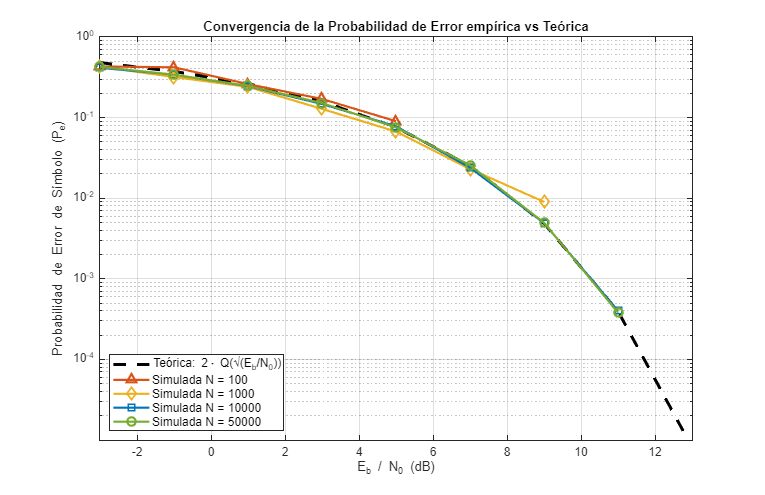


% --- CÁLCULO DE LA CURVA TEÓRICA ---
PeTheo = 2 * qfunc(sqrt(ebn0_lin));
PeTheo(PeTheo < 1e-7) = NaN;

% --- REPRESENTACIÓN GRÁFICA COMPARATIVA ---
figure('Name', 'Ejercicio 5.1 - Convergencia Monte Carlo vs N', 'Color', 'w', ...
       'Position', [100, 100, 850, 550]);

% 1. Curva Teórica de referencia
semilogy(EbN0_dB, PeTheo, 'k--', 'LineWidth', 2.5, ...
         'DisplayName', 'Teórica: 2\cdot Q(\surd(E_b/N_0))');
hold on;

% 2. Curvas simuladas para cada N
estilos = {'-^', '-d', '-s', '-o'};
colores = [0.85 0.33 0.10;   ... % N = 100 (Naranja)
           0.93 0.69 0.13;   ... % N = 1000 (Amarillo)
           0.00 0.45 0.74;   ... % N = 10000 (Azul)
           0.47 0.67 0.19];      % N = 50000 (Verde)

for idx_N = 1:length(N_vect)
    pe_plot = Pe_matriz(idx_N, :);
    pe_plot(pe_plot == 0) = NaN; % Para que la escala logarítmica no pinte ceros
    
    semilogy(EbN0_dB, pe_plot, estilos{idx_N}, 'LineWidth', 1.8, ...
             'MarkerSize', 7, 'Color', colores(idx_N, :), ...
             'DisplayName', sprintf('Simulada N = %d', N_vect(idx_N)));
end

grid on;
xlabel('E_b / N_0 (dB)');
ylabel('Probabilidad de Error de Símbolo (P_e)');
title('Convergencia de la Probabilidad de Error empírica vs Teórica');
xlim([min(EbN0_dB), max(EbN0_dB)]);
ylim([1e-5, 1]);
legend('Location', 'southwest', 'FontSize', 10);
hold off;

Análisis de la convergencia de la Probabilidad de Error (Pe*P**e*� vs Eb/N0*E**b*�/*N*0�):

- Resolución mínima medible (Pmin =1/N*P*min�=1/*N*):El menor error detectable en una simulación con N*N* símbolos es 1/N1/*N*. Por eso:

- Con N=100*N*=100, la curva se corta a los 5 dB5 dB (no puede medir por debajo de 10−210−2).

- Con N=1000*N*=1000, se interrumpe a los 9 dB9 dB (límite en 10−310−3).

- Con N=10000*N*=10000 y 5000050000, alcanza hasta 11 dB11 dB (Pe≈4⋅10−4*P**e*�≈4⋅10−4).

- Varianza estadística (Ley de los Grandes Números):Para valores pequeños de N*N* (100100 y 10001000), el escaso número de realizaciones produce oscilaciones y desviaciones respecto a la teoría (como el pico del rombo amarillo a 9 dB9 dB).

- Validación del sistema:A medida que N*N* aumenta (N≥10000*N*≥10000), la varianza del estimador tiende a cero y la curva experimental calca de forma exacta la curva teórica 2⋅Q(Eb/N0)2⋅*Q*(*E**b*�/*N*0��), validando que toda la cadena del sistema (modulación, canal AWGN, demodulador y detector de mínima distancia) funciona con precisión óptima